# Rise Time of Underdamped Second Order System Step Response

This live script derives two mathematical and one visual approximation for the rise time ($T_r$) of a second-order underdamped system model.

## Approximations

According to the Nise textbook (7th Ed.) "*a precise analytical relationship between rise time and damping ratio cannote be found,*" so we need to result to approximations.

### Simple Approximation

For *lightly damped* systems where $0.2 < \zeta < 0.8$ the simple appoximation

$T_r \approx \frac{1.8}{\omega_n$.

Below we complare this approximation with the numerical solution.

### Visual Approximation

The numerical solution is presented in *Nise Figure 4.16* which is reproduced below...

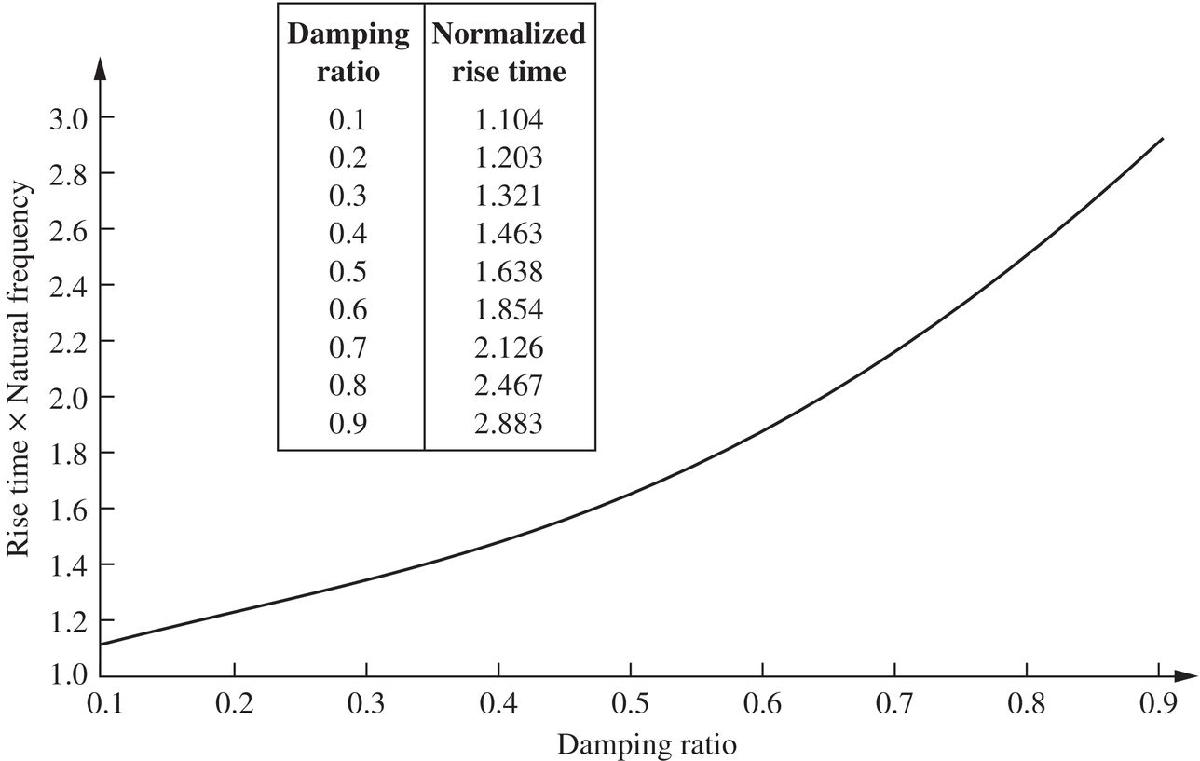

We will show how to reproduce this behavior graph below.

### Polynomial Approximation

The Nise text book also includes the following footnote:

*  Figure 4.16 can be approximated by the following polynomials*

$\omega_n T_r = 1.76 \zeta^3 - 0.417 \zeta ^2 +1.039 \zeta +1$  (max. error less than 1/2% for $0<\zeta<0.9$

## Reproduce Visual Approximation

The rise time is defined as the time it takes for the step response of a model to increase from 10% to 90% of the reference level.  To reproduce the graphical relationship from Nise Figure 4.16, we vary the damping ratio, simulate the resulting time response for a canonical second order model with unity gain, and measure the rise time.

To re

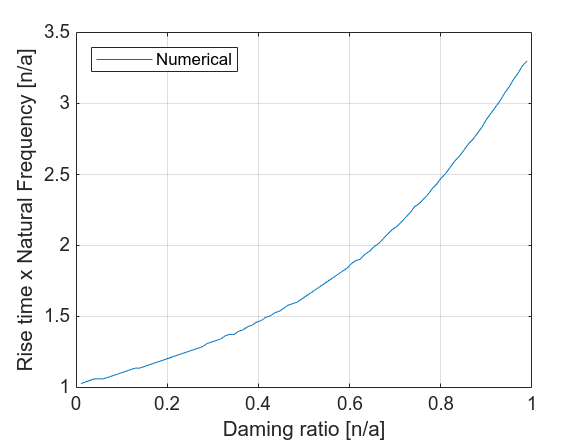

z = 0.5;
zz = linspace(0.01, 0.99, 100);
wT = [];
for ii = 1:length(zz)
    z = zz(ii);
    wn = 1.0;
    G = tf(wn^2,[1 2*z*wn wn]);
    [yy, tt] = step(G, linspace(0, 3*1.8/wn,500));
    Tr = tt(find(yy>=0.9, 1)) - tt(find(yy>=0.1, 1));
    wT(ii) = wn*Tr;
end

figure()
clf()
plot(zz,wT, "DisplayName", "Numerical")
xlabel("Daming ratio [n/a]")
ylabel("Rise time x Natural Frequency [n/a]")
grid("on")
legend("Location","northwest")

## Compare simple approximation

The simpole approximation


$$T_r \approx \frac{1.8}{\omega_n$$


for $0.2 < \zeta < 0.8$ can be written as 

$T_r \, \omega_n = 1.8$.

Which we can visualize as 

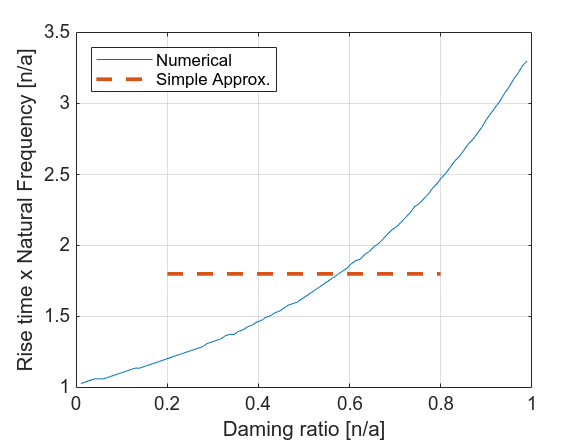

hold on;
plot([0.2 0.8], 1.8*[1 1], "--", "linewidth", 2, "DisplayName", "Simple Approx.")

## Compare the Nise polynomial approximation

We can evaluate the polynomial 

$\omega_n T_r = 1.76 \zeta^3 - 0.417 \zeta ^2 +1.039 \zeta +1$  (max. error less than 1/2% for $0<\zeta<0.9$

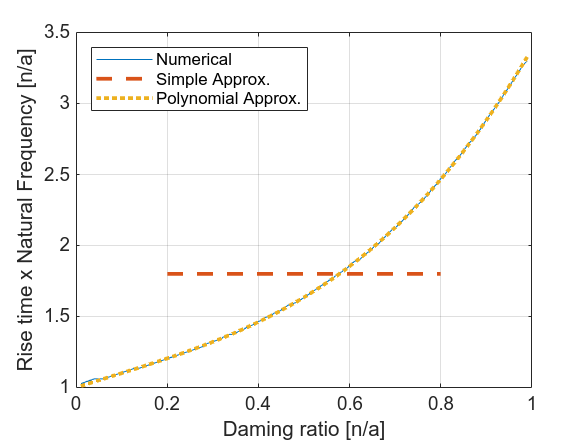

nisep = [1.76, -0.417, 1.039, 1];
zz = linspace(0.01, 0.99, 100);
nise_vals = polyval(nisep, zz);
hold on;
plot(zz, nise_vals, ":" , "linewidth", 2, "DisplayName","Polynomial Approx.")

## Summary

All of these methods are approximations of the rise time fo a second order system model.  They each have different pros and cons.